clc
clear
load b1.mat
load b2.mat
load a.mat
load vmax.mat
load maxx.mat
load M.mat
load dmdt.mat
load shadow.mat
load biomass.mat
load wuran.mat wuran

load rainfall.mat rainfall



%下面对a矩阵进行灵敏度分析处理
% sens_a_repeat_times = 0
% 
% sensa = zeros(5, 6);
% for i2 = 1 : sens_a_repeat_times
%     for i1 = 1 : 5
%         matrixval = min(a(i1, :)) * 0.1;
%         sensa(i1, :) = a(i1, :) + matrixval;
%     end
% end
% sensa = a;
% 
% %下面对b矩阵进行灵敏度分析处理
% sens_b_repeat_times = 3
% matrixvalindex = 9
% 
% sensb1 = zeros(6, 6);
% sensb2 = zeros(6, 6);
% 
% for i5 = 1 : sens_b_repeat_times
% 
%     for i3 = 1 : 6
%         matrixval = max(b1(i3, :));
%         for i4 = 1 : 6
%             if ( b1(i3, i4) < matrixval ) && ( b1(i3, i4) > 0 )
%                 matrixval = b1(i3, i4);
%             end         
%         end     %得到次小值
%         matrixval = matrixval * matrixvalindex;
%         
%         sensb1(i3, :) = b1(i3, :) + matrixval;
%         sensb1(i3, i3) = 0;
%     end
%     
%     for i3 = 1 : 6
%         matrixval = max(b2(i3, :));
%         for i4 = 1 : 6
%             if ( b2(i3, i4) < matrixval ) && ( b2(i3, i4) > 0 )
%                 matrixval = b2(i3, i4);
%             end         
%         end     %得到次小值
%         matrixval = matrixval * matrixvalindex;
%         
%         sensb2(i3, :) = b2(i3, :) + matrixval;
%         sensb2(i3, i3) = 0;
%     end
% 
% end



%计算不同降水条件下的vk用(有震荡)
fun2=@(k,x,myvmax) a(5,k).*myvmax./(1+a(1,k).*exp(a(2,k).*(x-a(3,k))))+a(5,k).*myvmax./(1+a(1,k).*exp(-a(2,k).*(x-a(3,k)-a(4,k)))) - 1.5.*myvmax;

%降水量变化索引
rainfallindex = 9

rainfallindex = 9


time = 10;%总时间
dt = 0.00001;%时间步长(越小越精确，但更占内存和时间)
len = round(time/dt);%计算总步数
m = M./100;%初始生物量为最大生物量的0.01
minm = 0.01*min(min(M));%最小的生物量（防止灭绝）



k=[1 4];%在这里写要加入的植物代号（加k2就写2，加k3就写3）
[w,num]=size(k);%计算植物数量num
  


zx=rainfall(rainfallindex, 1);%降水量波动中心值
bd=0;%rainfall(rainfallindex, 2);%降水量波动值（正100负100   共200）
tq=rand(1,len);
tq=bd*(tq-0.5);
tq=tq+zx;%降水量tq

w=0 %选污染

w = 0

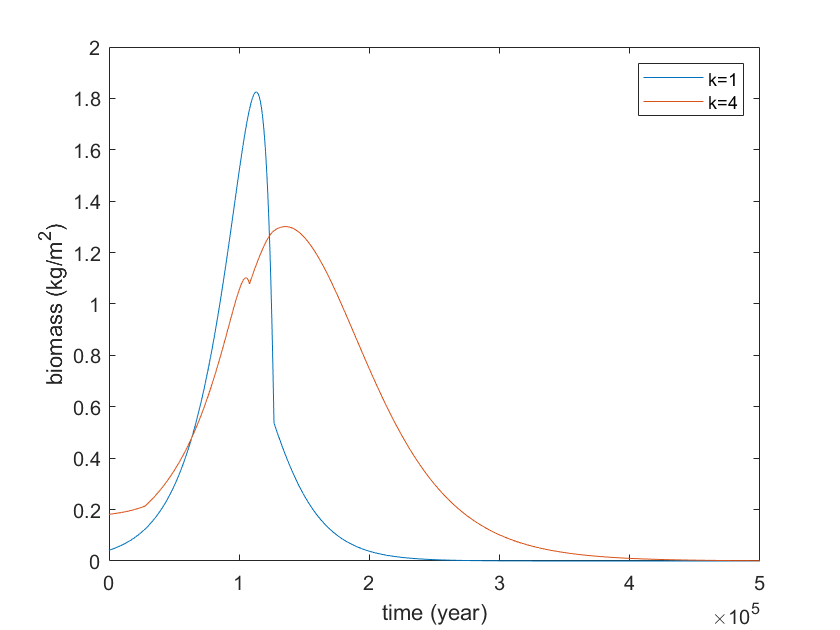


yin=m./biomass.*shadow;


mm=zeros(6,len);%记录各植物的数量
dmm=mm;
for t=dt:dt:time%随k2的生物量增长，k1的增长速率会如何变化
    tt=round(t/dt);
    other=0;
    for u=1:num%遍历全部植物

        f=k(u);
        
        
        

        %xz=minm-M(f);%允许共生和竞争
        xz=0;%只允许共生

        myvmax=vmax(f);
        for v=1:num
            other=other+b1(f,k(v))*m(k(v))^2+b2(f,k(v))*m(k(v));%计算其他植物对第u种的影响
        end
        
        ttrr=false;
        if (f==4 || f==5 || f==6)%草本在有木本的情况下增长速率翻倍
            v=max(0,yin(f)-sum(yin(1:3)))/yin(f)+1.5*sum(yin(1:3))/yin(f);
            ttrr=true;
        end
        
        
        dm=fun2(f,tq(tt),myvmax)*m(f)*(1- ( m(f)/( M(f)+max(xz,other))));
        
        if ttrr
            dm=dm*v;%有草本，加上增益
        end

        if w==1 || w==2
            dm=dm*(1-wuran(w));
        end


        m(f)=m(f)+dm*dt;

        if w==3
            m(f)=m(f)*(1-wuran(w)*0.00005);
        end

        if m(f)<=0
            m(f)=minm;%种群数量不能为负
        end

        mm(f,tt)=m(f);
        dmm(f,tt)=dm;%fun2(f,tq(tt),myvmax);
    end
    yin=m./biomass.*shadow;
end

tt=1:len/2;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%subplot(2, 2, 4)

plot(tt,dmm(1,tt),tt,dmm(4,tt))%,tt,mm(3,:),tt,mm(4,:),tt,mm(5,:),tt,mm(6,:))%画图

legend('k=1', 'k=4')%
legend('show')

xlabel('time (year)')
ylabel('biomass (kg/m^2)')
xlim([0 max(tt)])


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% subplot(2, 3, rainfallindex-10+3)
% 
% plot(tt,dmm(4,tt),tt,dmm(1,tt))%画图
% 
% legend('k=4', 'k=1')%
% legend('show')
% 
% xlabel('time (year)')
% %ylabel('biomass (kg/m^2)')
% xlim([0 max(tt)])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%plot(tt,dmm(1,:),tt,dmm(2,:))%画图
%plot(tt,mm(1,:),tt,mm(4,:))%画图
%plot(tt,mm(6,:))%画图
%plot(tt,dmm(6,:))%画图

% jiange=16000;%间隔几个点
% for i=1:len/jiange
%     mmm(:,i)=mm(:,i*jiange);
% end
% surf(mmm')
% bar3(mmm);
%yy=1:6;
%plot3(tt,yy,mmm)